BMS Thermistor Curve Fit

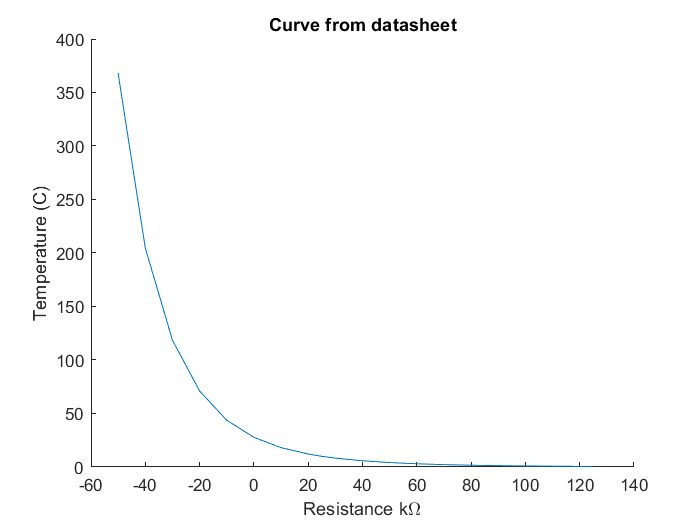

figure
hold on
title("Curve from datasheet")
plot(temp(:,1),temp(:,2));
ylabel("Temperature (C)");
xlabel("Resistance k\Omega");
hold off

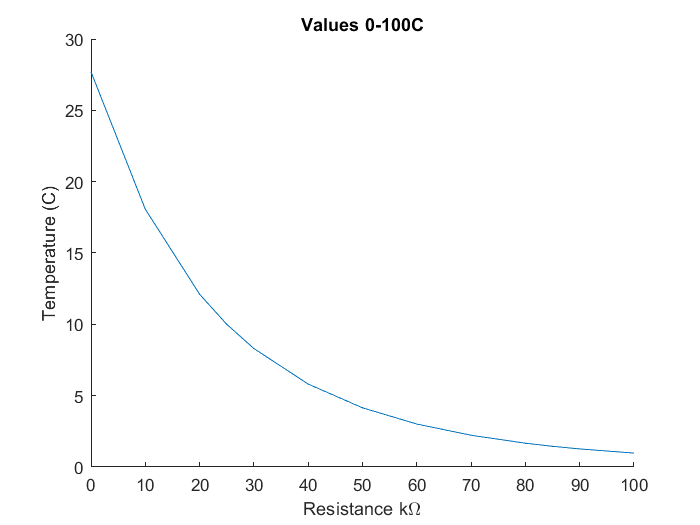

figure
hold on
title("Values 0-100C")
plot(temp(:,1),temp(:,2));
xlim([0,100]);
ylabel("Temperature (C)");
xlabel("Resistance k\Omega");
hold off 

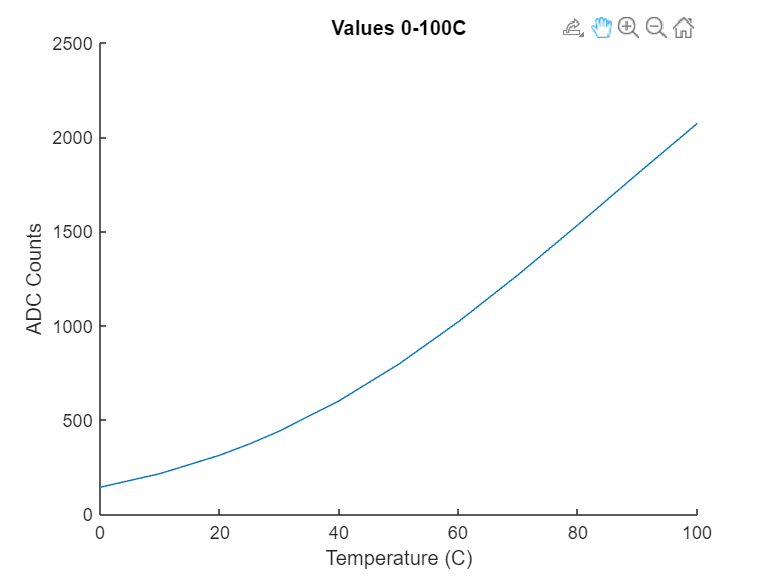

r1 = 1000;
vdd = 3.3;

vout = r1./(ResKOhm_sub+r1)*vdd;

counts_vout = (4096*r1)./(ResKOhm_sub*1000+r1);

figure
hold on
title("Values 0-100C")
plot(TempC_sub, counts_vout)
xlim([0,100]);
xlabel("Temperature (C)");
ylabel("ADC Counts");
hold off 

function [fitresult, gof] = createFit3(counts_vout, TempC_sub)
%CREATEFIT(COUNTS_VOUT,TEMPC_SUB)
%  Create a fit.
%
%  Data for 'Temps_0_100' fit:
%      X Input: counts_vout
%      Y Output: TempC_sub
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 12-Apr-2023 12:54:15


%% Fit: 'Temps_0_100'.
[xData, yData] = prepareCurveData( counts_vout, TempC_sub );

% Set up fittype and options.
ft = fittype( 'poly3' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Create a figure for the plots.
figure( 'Name', 'Temps_0_100' );

% Plot fit with data.
subplot( 2, 1, 1 );
h = plot( fitresult, xData, yData );
legend( h, 'TempC_sub vs. counts_vout', 'Temps_0_100', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'counts_vout', 'Interpreter', 'none' );
ylabel( 'TempC_sub', 'Interpreter', 'none' );
grid on

% Plot residuals.
subplot( 2, 1, 2 );
h = plot( fitresult, xData, yData, 'residuals' );
legend( h, 'Temps_0_100 - residuals', 'Zero Line', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'counts_vout', 'Interpreter', 'none' );
ylabel( 'TempC_sub', 'Interpreter', 'none' );
grid on


function [fitresult, gof] = createFit2(counts_vout, TempC_sub)
%CREATEFIT(COUNTS_VOUT,TEMPC_SUB)
%  Create a fit.
%
%  Data for 'Temps_0_100' fit:
%      X Input: counts_vout
%      Y Output: TempC_sub
%  Output:
%      fitresult : a fit object representing the fit.
%      gof : structure with goodness-of fit info.
%
%  See also FIT, CFIT, SFIT.

%  Auto-generated by MATLAB on 12-Apr-2023 12:55:07


%% Fit: 'Temps_0_100'.
[xData, yData] = prepareCurveData( counts_vout, TempC_sub );

% Set up fittype and options.
ft = fittype( 'poly2' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Create a figure for the plots.
figure( 'Name', 'Temps_0_100' );

% Plot fit with data.
subplot( 2, 1, 1 );
h = plot( fitresult, xData, yData );
legend( h, 'TempC_sub vs. counts_vout', 'Temps_0_100', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'counts_vout', 'Interpreter', 'none' );
ylabel( 'TempC_sub', 'Interpreter', 'none' );
grid on

% Plot residuals.
subplot( 2, 1, 2 );
h = plot( fitresult, xData, yData, 'residuals' );
legend( h, 'Temps_0_100 - residuals', 'Zero Line', 'Location', 'NorthEast', 'Interpreter', 'none' );
% Label axes
xlabel( 'counts_vout', 'Interpreter', 'none' );
ylabel( 'TempC_sub', 'Interpreter', 'none' );
grid on


